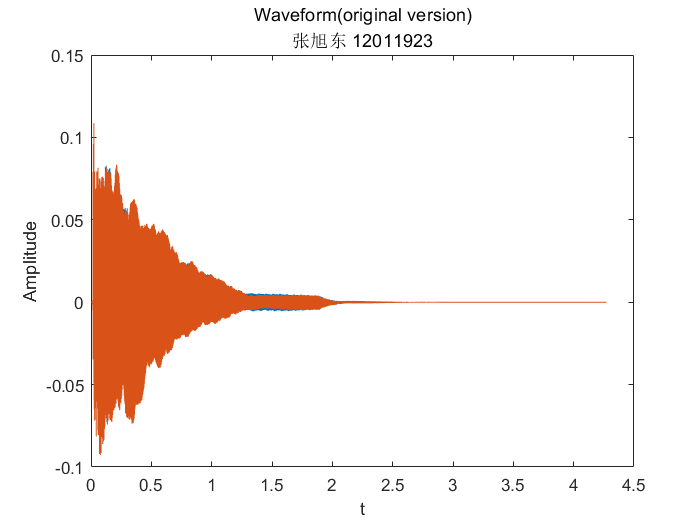

% scale='D';
% fs=8192;
% t=0.25;
% beat=4;%每个音符的持续时间

[y,fs]=audioread("d-1.mp3");
t=linspace(0,length(y)/fs,length(y));
f=linspace(-fs/2,fs/2-1,length(y));
plot(t,y);
xlabel('t');
ylabel('Amplitude')
title(['Waveform(original version)' newline '张旭东 12011923'])

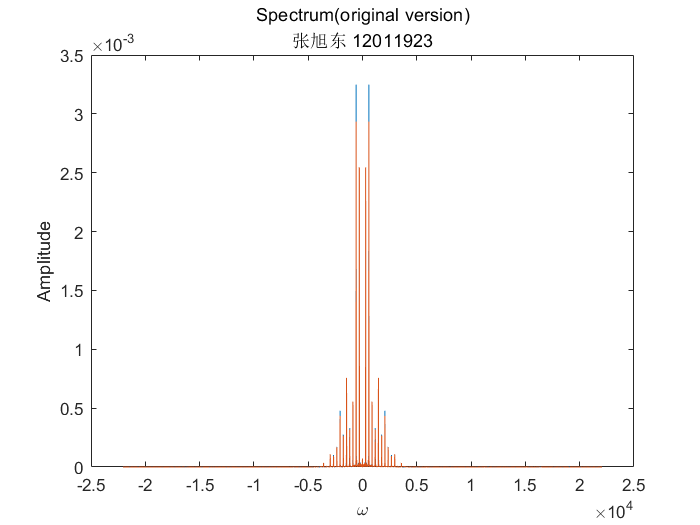

plot(f,abs(fftshift(fft(y./length(y)))));
xlabel('\omega');
ylabel('Amplitude')
title(['Spectrum(original version)' newline '张旭东 12011923'])

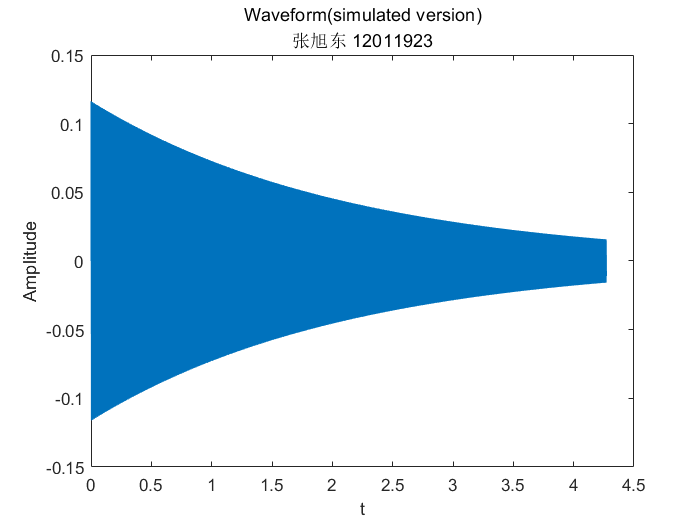


fc=293.5;
k1=[0.077 0.043 0.011 0.022 0.019 0.004 0.009];
y2=0;
for i =1:length(k1)
    y2=y2+k1(i)*sin(2*pi*i*fc*t).*exp(-2*t/(length(y)/fs));
end
plot(t,y2);
%axis([0 0.01 -1 1]);
xlabel('t');
ylabel('Amplitude')
title(['Waveform(simulated version)' newline '张旭东 12011923'])

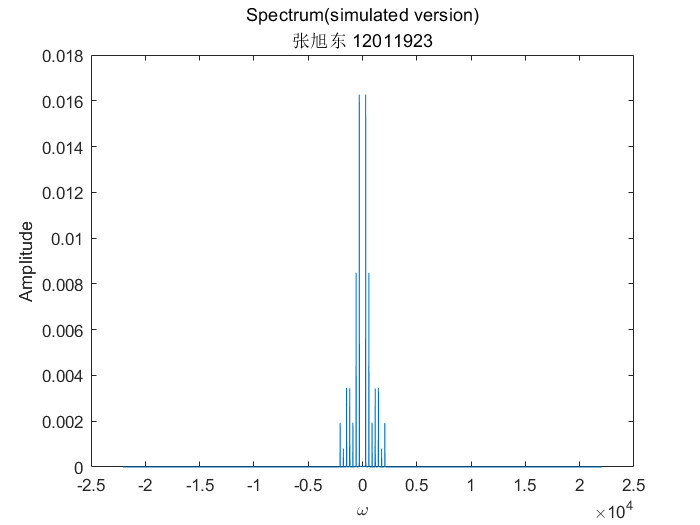

plot(f,abs(fftshift(fft(y2./length(y2)))));
xlabel('\omega');
ylabel('Amplitude')
title(['Spectrum(simulated version)' newline '张旭东 12011923'])


%sound(y,fs);
%sound(y2,fs);